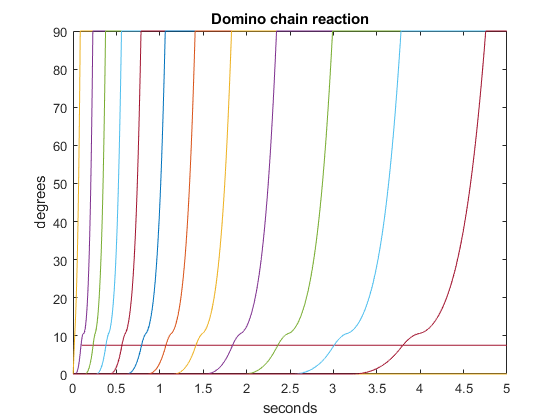

clear
height = 5.08/100;
width = 2.54/100;
thickness = 0.9525/100;
distance = 1/100;
density = 940;
mass = (height*width*thickness*density);

bricks = 12;
simulation_Time = 5;
step_size = 0.001;
samples = simulation_Time/step_size;

[theta, acc, omega,mg] = eulercalc(simulation_Time,step_size,mass,thickness,height);
tot_ang = zeros(1,samples,bricks);
tot_ang(:,:,1) = theta;

for c = 2:1:bricks
    b = acos(distance/height);
    collision_angle = (pi/2)-b;
    k = find(theta < collision_angle, 1, 'last' );
    x = sin(b)*height;

    height = height*1.5;
    width = width*1.5;
    thickness = thickness*1.5;
    mass = (height*width*thickness*density);
    J = mass*(height^2+thickness^2)/12;

    r = sqrt(thickness^2+x^2);
    Fr = acc(k)*J/height;
    Fx = Fr/cos(collision_angle);
    
    [theta, acc, omega, new_mg] = eulercalc_rest(simulation_Time,step_size,mass,thickness,height,Fx,mg,r,k,distance);

    tot_ang(:,:,c) = theta;
    mg = new_mg;
    distance = distance*1.5;

end
dlmwrite('tots.txt',tot_ang,";")
t = 0:step_size:simulation_Time-step_size;

for m= 1:1:bricks
    plot(t,rad2deg(tot_ang(:,:,m)))
    hold on;
end


title('Domino chain reaction')
xlabel('seconds')
ylabel('degrees')